- Plot the distribution

- Execute the testing

bins = 0:186;
titles = ["Correlation", "Correlation with trace compression", "Euclidean distance", "Euclidean distance with trace compression"];
format short
psame = 0.1360;
indexesCharacterization = [1 5 6 10];

%Load data
load('./attack_results/v7_first_op.mat')
load('./results_characterization/v7_first_op.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

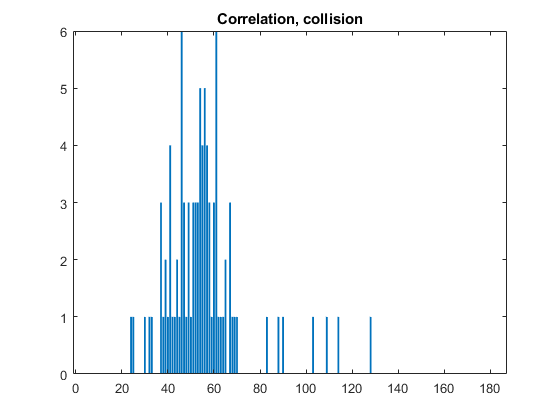

Parameters:


Mean= 55.2903


Variance = 291.0778


estP = 0.2973

Compared to characterization: 


Mean= 150.4317


Variance= 28.7667


P= 0.80877


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = 0.0960

st = struct with fields:
    chi2stat: 10.7616
          df: 6
       edges: [-0.5000 51.5000 52.5000 53.5000 54.5000 55.5000 56.5000 57.5000 58.5000 186.5000]
           O: [38 3 3 5 4 5 4 3 28]
           E: [25.4738 5.2553 5.6204 5.8556 5.9446 5.8823 5.6749 5.3390 27.9541]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.0102e-63

st = struct with fields:
    chi2stat: 313.0007
          df: 7
       edges: [-0.5000 146.5000 147.5000 148.5000 149.5000 150.5000 151.5000 152.5000 153.5000 154.5000 186.5000]
           O: [93 0 0 0 0 0 0 0 0 0]
           E: [21.3029 5.4596 6.0847 6.5631 6.8470 6.9040 6.7236 6.3192 5.7271 21.0688]


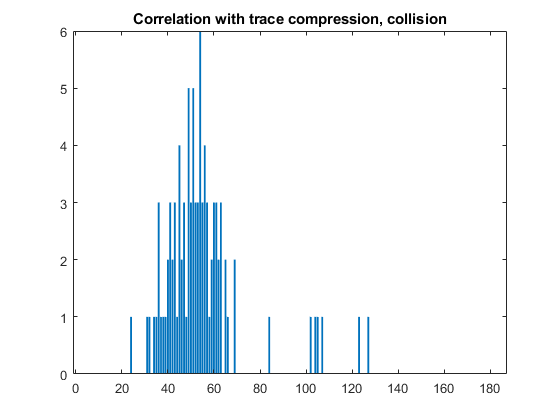

Parameters:


Mean= 54.6882


Variance = 322.4778


estP = 0.2940

Compared to characterization: 


Mean= 132.5168


Variance= 38.1044


P= 0.71246


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 0.0044

st = struct with fields:
    chi2stat: 20.6159
          df: 7
       edges: [-0.5000 50.5000 51.5000 52.5000 53.5000 54.5000 55.5000 56.5000 57.5000 58.5000 186.5000]
           O: [40 5 3 3 6 3 4 3 1 25]
           E: [23.4477 5.0917 5.5053 5.7969 5.9463 5.9436 5.7905 5.5002 5.0948 24.8830]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 9.5455e-55

st = struct with fields:
    chi2stat: 270.9512
          df: 7
       edges: [-0.5000 128.5000 129.5000 130.5000 131.5000 132.5000 133.5000 134.5000 135.5000 136.5000 186.5000]
           O: [93 0 0 0 0 0 0 0 0 0]
           E: [23.7642 5.0188 5.4524 5.7750 5.9621 5.9978 5.8778 5.6097 5.2122 24.3300]


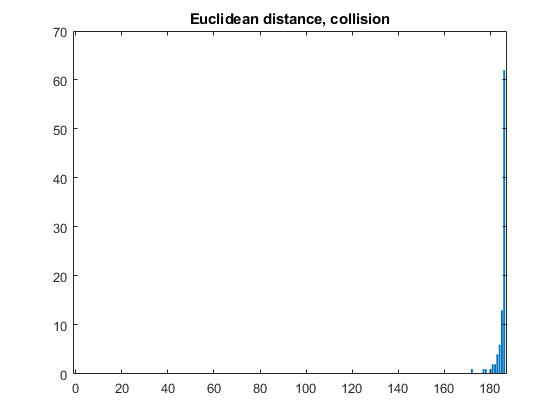

Parameters:


Mean= 185.0108


Variance = 4.7934


estP = 0.9947

Compared to characterization: 


Mean= 57.3774


Variance= 39.6776


P= 0.30848


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.6165e-11

st = struct with fields:
    chi2stat: 45.3876
          df: 1
       edges: [-0.5000 183.5000 184.5000 185.5000 186.5000]
           O: [12 6 13 62]
           E: [7.2394 16.9661 34.3030 34.4915]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.7712e-42

st = struct with fields:
    chi2stat: 209.5327
          df: 6
       edges: [-0.5000 53.5000 54.5000 55.5000 56.5000 57.5000 58.5000 59.5000 60.5000 186.5000]
           O: [0 0 0 0 0 0 0 0 93]
           E: [25.2260 5.1735 5.5388 5.7800 5.8805 5.8345 5.6465 5.3316 28.5886]


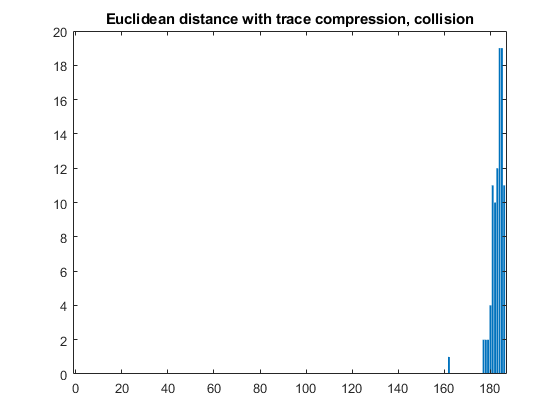

Parameters:


Mean= 182.9462


Variance = 9.5514


estP = 0.9836

Compared to characterization: 


Mean= 66.5867


Variance= 42.7491


P= 0.35799


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 0.0010

st = struct with fields:
    chi2stat: 16.1985
          df: 3
       edges: [-0.5000 180.5000 181.5000 182.5000 183.5000 184.5000 186.5000]
           O: [11 11 10 12 19 30]
           E: [8.1607 9.7419 16.0337 20.9957 20.5079 17.5601]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.2270e-39

st = struct with fields:
    chi2stat: 192.3527
          df: 5
       edges: [-0.5000 63.5000 64.5000 65.5000 66.5000 67.5000 68.5000 69.5000 186.5000]
           O: [0 0 0 0 0 0 0 93]
           E: [29.8076 5.2847 5.5310 5.6543 5.6471 5.5105 5.2549 30.3099]


%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

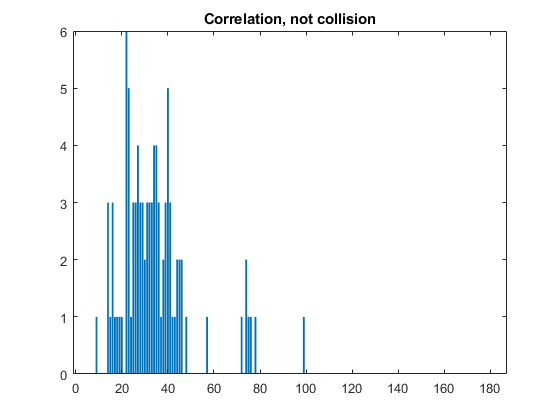

Parameters:


Mean= 34.2366


Variance = 248.7478


estP = 0.1841

Compared to characterization: 


Mean= 150.4317


Variance= 28.7667


P= 0.80877


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.7897e-08

st = struct with fields:
    chi2stat: 51.8619
          df: 8
       edges: [-0.5000 29.5000 30.5000 31.5000 32.5000 33.5000 34.5000 35.5000 36.5000 37.5000 38.5000 186.5000]
           O: [40 2 3 3 3 4 4 3 1 2 28]
           E: [17.3046 5.2904 6.0059 6.5627 6.9089 7.0137 6.8714 6.5019 5.9464 5.2599 19.3344]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.0102e-63

st = struct with fields:
    chi2stat: 313.0007
          df: 7
       edges: [-0.5000 146.5000 147.5000 148.5000 149.5000 150.5000 151.5000 152.5000 153.5000 154.5000 186.5000]
           O: [93 0 0 0 0 0 0 0 0 0]
           E: [21.3029 5.4596 6.0847 6.5631 6.8470 6.9040 6.7236 6.3192 5.7271 21.0688]


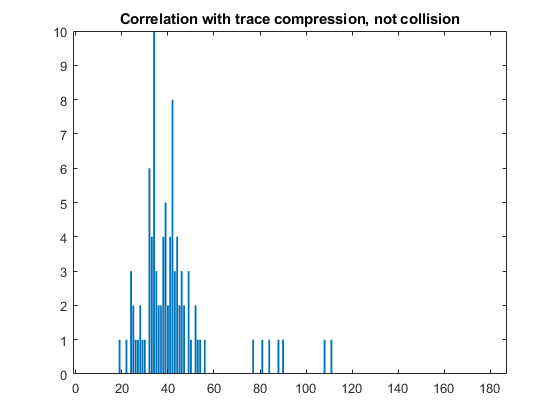

Parameters:


Mean= 41.9677


Variance = 268.1837


estP = 0.2256

Compared to characterization: 


Mean= 132.5168


Variance= 38.1044


P= 0.71246


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.5591e-04

st = struct with fields:
    chi2stat: 28.8219
          df: 7
       edges: [-0.5000 37.5000 38.5000 39.5000 40.5000 41.5000 42.5000 43.5000 44.5000 45.5000 186.5000]
           O: [40 4 5 2 4 8 3 4 2 21]
           E: [20.3158 5.2535 5.8091 6.2204 6.4542 6.4926 6.3353 5.9994 5.5162 24.6034]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 9.5455e-55

st = struct with fields:
    chi2stat: 270.9512
          df: 7
       edges: [-0.5000 128.5000 129.5000 130.5000 131.5000 132.5000 133.5000 134.5000 135.5000 136.5000 186.5000]
           O: [93 0 0 0 0 0 0 0 0 0]
           E: [23.7642 5.0188 5.4524 5.7750 5.9621 5.9978 5.8778 5.6097 5.2122 24.3300]


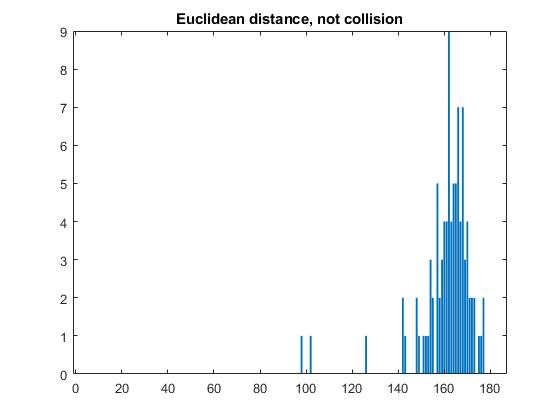

Parameters:


Mean= 161


Variance = 149.6957


estP = 0.8656

Compared to characterization: 


Mean= 57.3774


Variance= 39.6776


P= 0.30848


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.8932e-05

st = struct with fields:
    chi2stat: 35.8214
          df: 8
       edges: [-0.5000 156.5000 157.5000 158.5000 159.5000 160.5000 161.5000 162.5000 163.5000 164.5000 165.5000 186.5000]
           O: [17 5 2 3 4 4 9 4 5 5 35]
           E: [15.4423 5.2463 6.2012 7.0328 7.6429 7.9486 7.8995 7.4905 6.7652 5.8090 15.5218]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.7712e-42

st = struct with fields:
    chi2stat: 209.5327
          df: 6
       edges: [-0.5000 53.5000 54.5000 55.5000 56.5000 57.5000 58.5000 59.5000 60.5000 186.5000]
           O: [0 0 0 0 0 0 0 0 93]
           E: [25.2260 5.1735 5.5388 5.7800 5.8805 5.8345 5.6465 5.3316 28.5886]


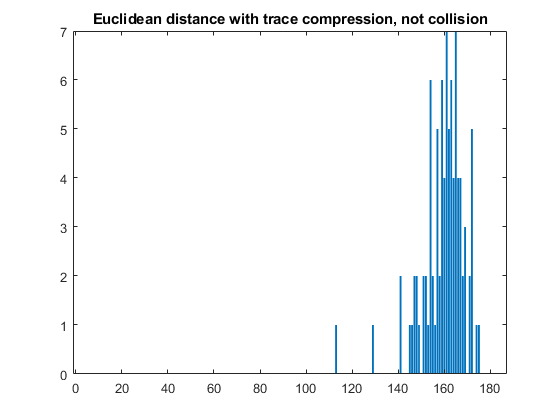

Parameters:


Mean= 159.6774


Variance = 88.5252


estP = 0.8585

Compared to characterization: 


Mean= 66.5867


Variance= 42.7491


P= 0.35799


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 4.2673e-04

st = struct with fields:
    chi2stat: 28.2631
          df: 8
       edges: [-0.5000 155.5000 156.5000 157.5000 158.5000 159.5000 160.5000 161.5000 162.5000 163.5000 164.5000 186.5000]
           O: [24 1 5 2 6 4 7 5 6 4 29]
           E: [17.4918 5.5278 6.4074 7.1341 7.6211 7.8015 7.6426 7.1545 6.3902 5.4365 14.3926]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.2270e-39

st = struct with fields:
    chi2stat: 192.3527
          df: 5
       edges: [-0.5000 63.5000 64.5000 65.5000 66.5000 67.5000 68.5000 69.5000 186.5000]
           O: [0 0 0 0 0 0 0 93]
           E: [29.8076 5.2847 5.5310 5.6543 5.6471 5.5105 5.2549 30.3099]


%Not collision distributions
for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
     %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

%Load data
load('./attack_results/v7_second_op.mat')
load('./results_characterization/v7_second_op_3.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

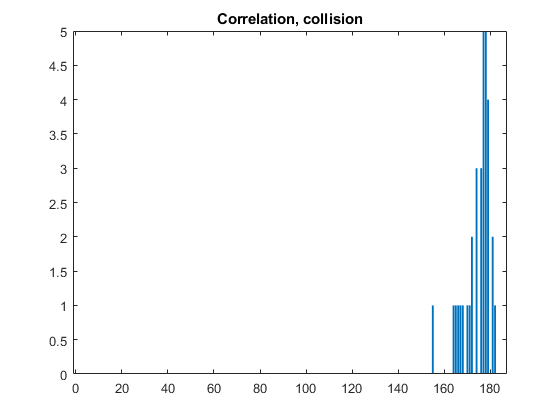

Parameters:


Mean= 174.375


Variance = 681.7816

estP = 0.9376

Compared to characterization: 


Mean= 178.1677


Variance= 7.5025


P= 0.95789


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 1.3479
          df: 0
       edges: [-0.5000 174.5000 186.5000]
           O: [13 20]
           E: [16.3345 16.6655]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 1.1036e-13

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 9.0804
          df: 0
       edges: [-0.5000 178.5000 186.5000]
           O: [26 7]
           E: [17.3564 15.6436]


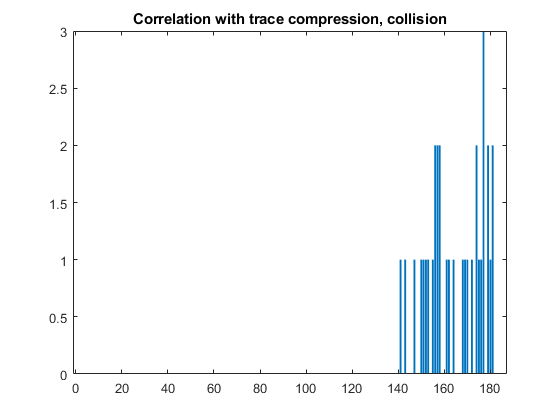

Parameters:


Mean= 164.5455


Variance = 145.8807


estP = 0.8847

Compared to characterization: 


Mean= 159.7147


Variance= 22.5707


P= 0.85868


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.1279
          df: 0
       edges: [-0.5000 164.5000 186.5000]
           O: [17 16]
           E: [15.9732 17.0268]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 2.2639e-09

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.3013
          df: 0
       edges: [-0.5000 159.5000 186.5000]
           O: [14 19]
           E: [15.5741 17.4259]


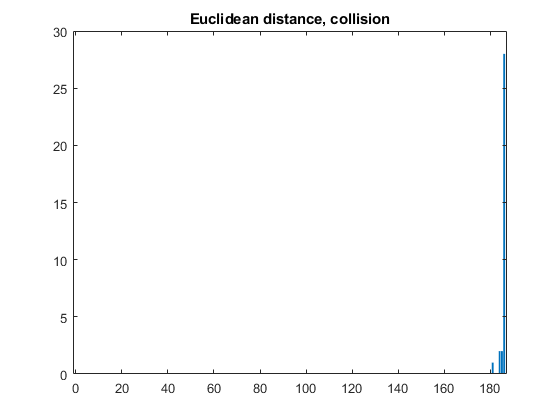

Parameters:


Mean= 185.6667


Variance = 0.97917


estP = 0.9982

Compared to characterization: 


Mean= 43.5655


Variance= 33.3615


P= 0.23422


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 2.8368
          df: 0
       edges: [-0.5000 185.5000 186.5000]
           O: [5 28]
           E: [9.3615 23.6385]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 33.2142
          df: 0
       edges: [-0.5000 43.5000 186.5000]
           O: [0 33]
           E: [16.5534 16.4466]


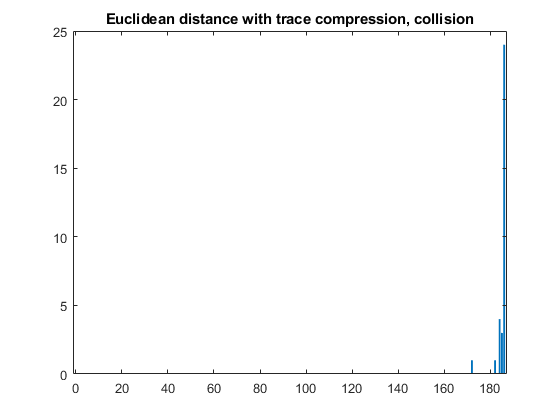

Parameters:


Mean= 185.1212


Variance = 6.4223


estP = 0.9953

Compared to characterization: 


Mean= 48.5014


Variance= 35.8542


P= 0.26076


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 14.8295
          df: 0
       edges: [-0.5000 184.5000 185.5000 186.5000]
           O: [6 3 24]
           E: [7.2488 12.0753 13.6759]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 33.6987
          df: 0
       edges: [-0.5000 48.5000 186.5000]
           O: [0 33]
           E: [16.6728 16.3272]


%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

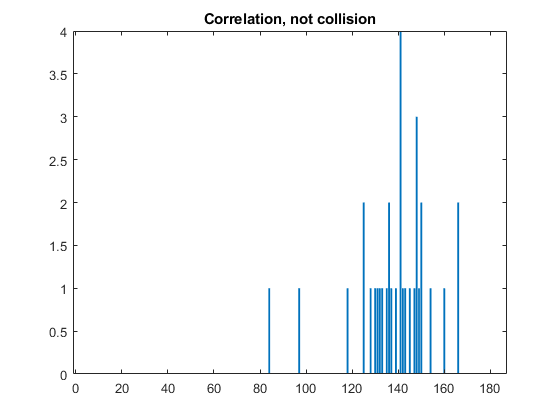

Parameters:


Mean= 138.3636


Variance = 276.4886


estP = 0.7439

Compared to characterization: 


Mean= 178.1677


Variance= 7.5025


P= 0.95789


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.8328
          df: 0
       edges: [-0.5000 138.5000 186.5000]
           O: [14 19]
           E: [16.6211 16.3789]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 29.7434
          df: 0
       edges: [-0.5000 178.5000 186.5000]
           O: [33 0]
           E: [17.3564 15.6436]


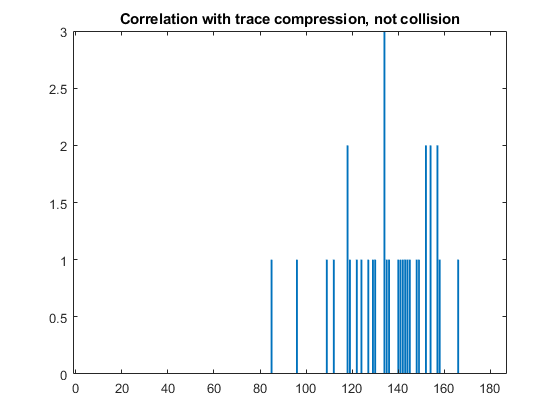

Parameters:


Mean= 135.2727


Variance = 342.3295


estP = 0.7273

Compared to characterization: 


Mean= 159.7147


Variance= 22.5707


P= 0.85868


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.0831
          df: 0
       edges: [-0.5000 135.5000 186.5000]
           O: [16 17]
           E: [16.8278 16.1722]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 32.8074
          df: 0
       edges: [-0.5000 159.5000 186.5000]
           O: [32 1]
           E: [15.5741 17.4259]


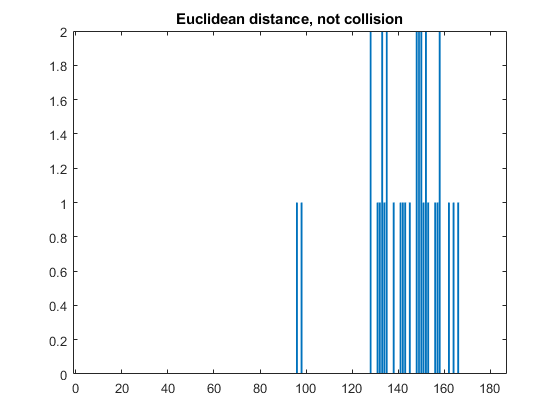

Parameters:


Mean= 142.8788


Variance = 252.6098


estP = 0.7682

Compared to characterization: 


Mean= 43.5655


Variance= 33.3615


P= 0.23422


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.2493
          df: 0
       edges: [-0.5000 142.5000 186.5000]
           O: [14 19]
           E: [15.4310 17.5690]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 33.2142
          df: 0
       edges: [-0.5000 43.5000 186.5000]
           O: [0 33]
           E: [16.5534 16.4466]


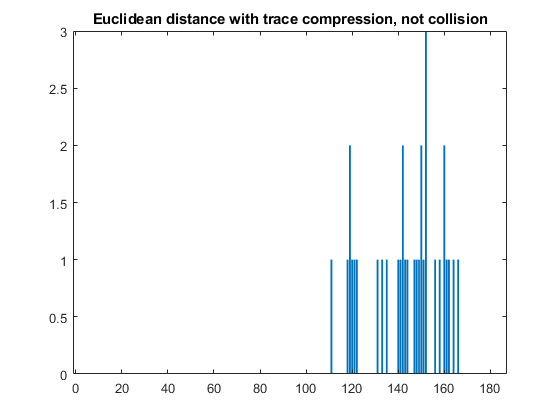

Parameters:


Mean= 143


Variance = 240.25


estP = 0.7688

Compared to characterization: 


Mean= 48.5014


Variance= 35.8542


P= 0.26076


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 0.7234
          df: 0
       edges: [-0.5000 143.5000 186.5000]
           O: [15 18]
           E: [17.4389 15.5611]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 33.6987
          df: 0
       edges: [-0.5000 48.5000 186.5000]
           O: [0 33]
           E: [16.6728 16.3272]


%Not collision distributions
for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
     %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

%Load data
load('./attack_results/v9_first_op.mat')
load('./results_characterization/v9_first_op.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

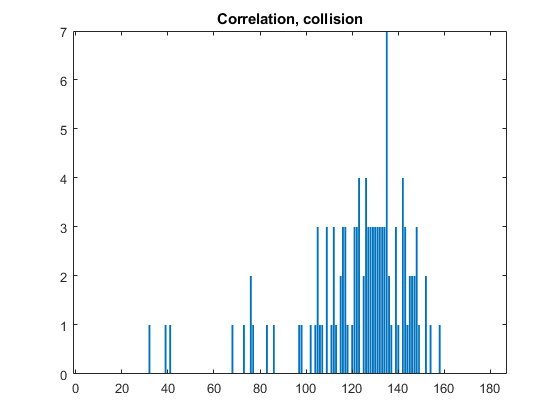

Parameters:


Mean= 122.8142


Variance = 527.9741


estP = 0.6603

Compared to characterization: 


Mean= 137.3556


Variance= 35.9225


P= 0.73847


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.5392e-14

st = struct with fields:
    chi2stat: 87.6852
          df: 10
       edges: [-0.5000 117.5000 118.5000 119.5000 120.5000 121.5000 122.5000 123.5000 124.5000 125.5000 126.5000 127.5000 128.5000 186.5000]
           O: [35 1 0 1 3 3 4 0 2 4 3 3 54]
           E: [23.1187 5.2081 5.7846 6.2776 6.6555 6.8923 6.9706 6.8836 6.6363 6.2447 5.7344 5.1376 21.4559]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 5.8213e-24

st = struct with fields:
    chi2stat: 131.5023
          df: 9
       edges: [-0.5000 132.5000 133.5000 134.5000 135.5000 136.5000 137.5000 138.5000 139.5000 140.5000 141.5000 142.5000 186.5000]
           O: [71 3 3 7 2 1 0 3 1 0 4 18]
           E: [23.4618 5.6408 6.2998 6.8519 7.2553 7.4768 7.4963 7.3095 6.9290 6.3829 5.7116 22.1845]


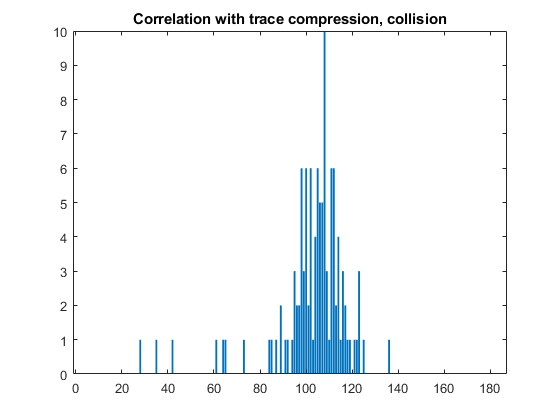

Parameters:


Mean= 102.7168


Variance = 258.8655


estP = 0.5522

Compared to characterization: 


Mean= 72.8189


Variance= 44.3103


P= 0.3915


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 0.0028

st = struct with fields:
    chi2stat: 25.2060
          df: 9
       edges: [-0.5000 97.5000 98.5000 99.5000 100.5000 101.5000 102.5000 103.5000 104.5000 105.5000 106.5000 107.5000 186.5000]
           O: [22 6 3 6 2 6 1 4 6 5 5 47]
           E: [24.9283 5.1951 5.6954 6.1112 6.4178 6.5961 6.6346 6.5305 6.2900 5.9281 5.4665 27.2065]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 6.9893e-60

st = struct with fields:
    chi2stat: 302.6976
          df: 9
       edges: [-0.5000 67.5000 68.5000 69.5000 70.5000 71.5000 72.5000 73.5000 74.5000 75.5000 76.5000 77.5000 186.5000]
           O: [6 0 0 0 0 0 1 0 0 0 0 106]
           E: [24.0397 5.2619 5.7896 6.2259 6.5445 6.7253 6.7571 6.6386 6.3783 5.9936 5.5088 27.1367]


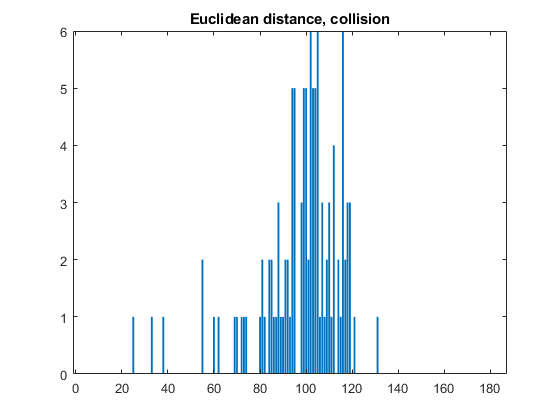

Parameters:


Mean= 97.469


Variance = 324.6441


estP = 0.5240

Compared to characterization: 


Mean= 112.1848


Variance= 44.5212


P= 0.60314


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 9.5738e-07

st = struct with fields:
    chi2stat: 44.9132
          df: 9
       edges: [-0.5000 92.5000 93.5000 94.5000 95.5000 96.5000 97.5000 98.5000 99.5000 100.5000 101.5000 102.5000 186.5000]
           O: [31 1 5 5 0 0 3 5 5 2 6 50]
           E: [26.2968 5.3248 5.8000 6.1839 6.4537 6.5925 6.5915 6.4507 6.1787 5.7922 5.3141 26.0211]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 5.9134e-29

st = struct with fields:
    chi2stat: 155.6605
          df: 9
       edges: [-0.5000 107.5000 108.5000 109.5000 110.5000 111.5000 112.5000 113.5000 114.5000 115.5000 116.5000 117.5000 186.5000]
           O: [83 1 2 3 1 4 0 2 1 6 2 8]
           E: [27.1804 5.5015 5.9833 6.3654 6.6238 6.7412 6.7093 6.5296 6.2131 5.7796 5.2553 24.1177]


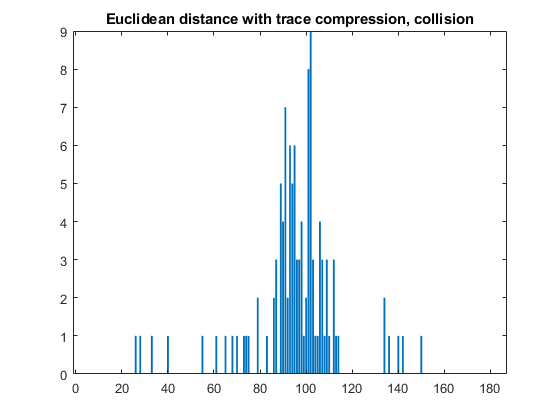

Parameters:


Mean= 95.3009


Variance = 361.9979


estP = 0.5124

Compared to characterization: 


Mean= 77.4269


Variance= 45.1961


P= 0.41627


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 5.4056e-04

st = struct with fields:
    chi2stat: 29.4660
          df: 9
       edges: [-0.5000 90.5000 91.5000 92.5000 93.5000 94.5000 95.5000 96.5000 97.5000 98.5000 99.5000 100.5000 186.5000]
           O: [29 7 2 6 5 6 3 3 4 1 2 45]
           E: [27.1870 5.4123 5.8723 6.2366 6.4833 6.5971 6.5708 6.4060 6.1128 5.7093 5.2191 25.1933]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 2.3737e-173

Chi-squared test:


h = 1

p = 1.8292e-54

st = struct with fields:
    chi2stat: 277.1342
          df: 9
       edges: [-0.5000 72.5000 73.5000 74.5000 75.5000 76.5000 77.5000 78.5000 79.5000 80.5000 81.5000 82.5000 186.5000]
           O: [9 1 1 1 0 0 0 2 0 0 0 99]
           E: [26.2675 5.4351 5.9187 6.3031 6.5649 6.6881 6.6651 6.4979 6.1978 5.7840 5.2817 25.3962]


%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

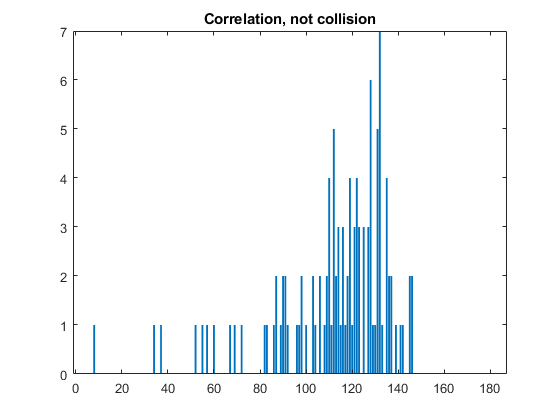

Parameters:


Mean= 112.4956


Variance = 621.8772


estP = 0.6048

Compared to characterization: 


Mean= 137.3556


Variance= 35.9225


P= 0.73847


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 8.4667e-12

st = struct with fields:
    chi2stat: 71.2987
          df: 9
       edges: [-0.5000 107.5000 108.5000 109.5000 110.5000 111.5000 112.5000 113.5000 114.5000 115.5000 116.5000 117.5000 186.5000]
           O: [31 1 2 4 1 5 2 3 1 3 1 59]
           E: [25.5612 5.3372 5.8453 6.2622 6.5620 6.7252 6.7403 6.6057 6.3296 5.9292 5.4292 25.6729]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 8.6785e-58

st = struct with fields:
    chi2stat: 292.8237
          df: 9
       edges: [-0.5000 132.5000 133.5000 134.5000 135.5000 136.5000 137.5000 138.5000 139.5000 140.5000 141.5000 142.5000 186.5000]
           O: [97 1 0 4 2 2 0 1 0 1 1 4]
           E: [23.4618 5.6408 6.2998 6.8519 7.2553 7.4768 7.4963 7.3095 6.9290 6.3829 5.7116 22.1845]


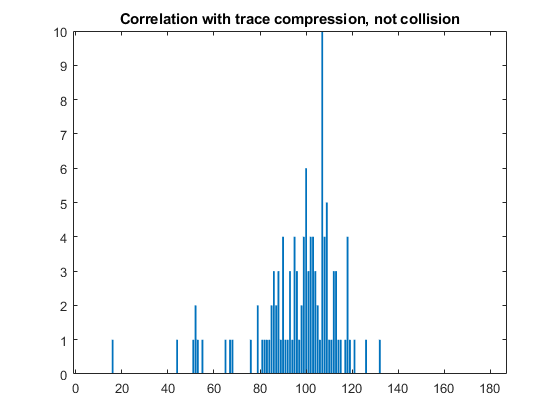

Parameters:


Mean= 96.6814


Variance = 321.8797


estP = 0.5198

Compared to characterization: 


Mean= 72.8189


Variance= 44.3103


P= 0.3915


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1.0000

Chi-squared test:


h = 1

p = 4.3038e-07

st = struct with fields:
    chi2stat: 46.7849
          df: 9
       edges: [-0.5000 91.5000 92.5000 93.5000 94.5000 95.5000 96.5000 97.5000 98.5000 99.5000 100.5000 101.5000 186.5000]
           O: [33 1 3 1 4 3 1 2 4 6 3 52]
           E: [25.2462 5.2155 5.7061 6.1108 6.4056 6.5725 6.6009 6.4889 6.2434 5.8795 5.4190 27.1117]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 8.4447e-310

Chi-squared test:


h = 1

p = 7.9534e-54

st = struct with fields:
    chi2stat: 274.1188
          df: 9
       edges: [-0.5000 67.5000 68.5000 69.5000 70.5000 71.5000 72.5000 73.5000 74.5000 75.5000 76.5000 77.5000 186.5000]
           O: [9 1 0 0 0 0 0 0 0 1 0 102]
           E: [24.0397 5.2619 5.7896 6.2259 6.5445 6.7253 6.7571 6.6386 6.3783 5.9936 5.5088 27.1367]


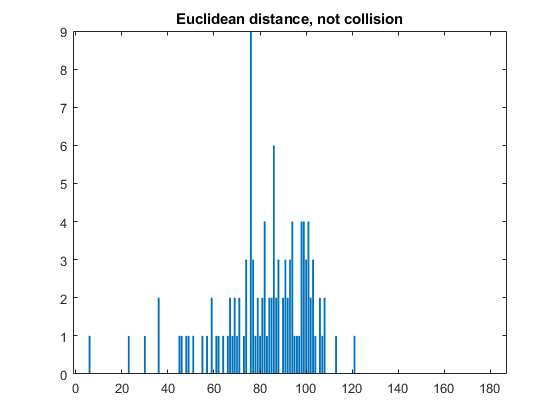

Parameters:


Mean= 81.8938


Variance = 385.4708


estP = 0.4403

Compared to characterization: 


Mean= 112.1848


Variance= 44.5212


P= 0.60314


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 2.6789e-08

st = struct with fields:
    chi2stat: 53.1996
          df: 9
       edges: [-0.5000 76.5000 77.5000 78.5000 79.5000 80.5000 81.5000 82.5000 83.5000 84.5000 85.5000 86.5000 186.5000]
           O: [39 3 1 2 1 2 4 1 2 2 6 50]
           E: [24.0880 5.1544 5.6662 6.0934 6.4110 6.5997 6.6477 6.5524 6.3203 5.9661 5.5117 27.9890]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 1

p = 1.2637e-64

st = struct with fields:
    chi2stat: 325.0340
          df: 9
       edges: [-0.5000 107.5000 108.5000 109.5000 110.5000 111.5000 112.5000 113.5000 114.5000 115.5000 116.5000 117.5000 186.5000]
           O: [109 2 0 0 0 0 1 0 0 0 0 1]
           E: [27.1804 5.5015 5.9833 6.3654 6.6238 6.7412 6.7093 6.5296 6.2131 5.7796 5.2553 24.1177]


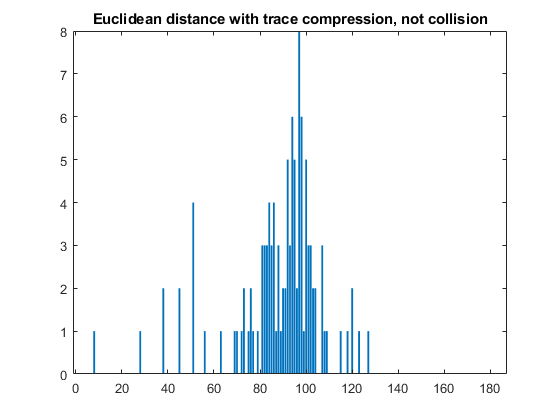

Parameters:


Mean= 88.115


Variance = 371.192


estP = 0.4737

Compared to characterization: 


Mean= 77.4269


Variance= 45.1961


P= 0.41627


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 5.3445e-09

st = struct with fields:
    chi2stat: 59.1076
          df: 10
       edges: [-0.5000 82.5000 83.5000 84.5000 85.5000 86.5000 87.5000 88.5000 89.5000 90.5000 91.5000 92.5000 93.5000 186.5000]
           O: [28 3 4 3 4 1 3 1 2 2 5 3 54]
           E: [23.1605 5.0047 5.5242 5.9674 6.3087 6.5276 6.6106 6.5526 6.3574 6.0373 5.6119 5.1061 24.2311]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 1.1178e-63

Chi-squared test:


h = 1

p = 4.3077e-35

st = struct with fields:
    chi2stat: 185.1241
          df: 9
       edges: [-0.5000 72.5000 73.5000 74.5000 75.5000 76.5000 77.5000 78.5000 79.5000 80.5000 81.5000 82.5000 186.5000]
           O: [15 2 0 1 2 1 0 1 0 3 3 85]
           E: [26.2675 5.4351 5.9187 6.3031 6.5649 6.6881 6.6651 6.4979 6.1978 5.7840 5.2817 25.3962]


%Not collision distributions
for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
     %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

%Load data
load('./attack_results/v9_second_op.mat')
load('./results_characterization/v9_second_op.mat')

% frequencyCount = zeros(4,1);
notCollisionResults = successMat(1,successMat(2,:,1)==0,:);
collisionResults = successMat(1,successMat(2,:,1)==1,:);

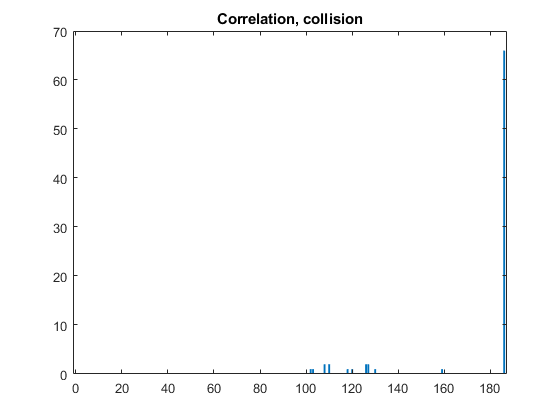

Parameters:


Mean= 174.375


Variance = 681.7816


estP = 0.9375

Compared to characterization: 


Mean= 159.6261


Variance= 22.6342


P= 0.8582


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 8.7986e-101

st = struct with fields:
    chi2stat: 485.8555
          df: 7
       edges: [-0.5000 170.5000 171.5000 172.5000 173.5000 174.5000 175.5000 176.5000 177.5000 178.5000 186.5000]
           O: [14 0 0 0 0 0 0 0 0 66]
           E: [9.8055 5.2817 6.9092 8.3869 9.3991 9.6677 9.0635 7.6809 5.8254 7.9800]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 3.8873e-149

Chi-squared test:


h = 1

p = 7.9655e-38

st = struct with fields:
    chi2stat: 187.6687
          df: 6
       edges: [-0.5000 156.5000 157.5000 158.5000 159.5000 160.5000 161.5000 162.5000 163.5000 186.5000]
           O: [13 0 0 1 0 0 0 0 66]
           E: [20.0806 5.5450 6.1599 6.5655 6.7056 6.5542 6.1217 5.4554 16.8120]


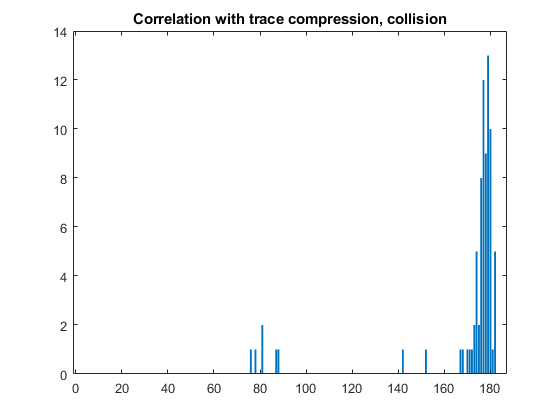

Parameters:


Mean= 169.3875


Variance = 662.5948


estP = 0.9107

Compared to characterization: 


Mean= 122.3458


Variance= 41.87


P= 0.65777


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.1464e-59

st = struct with fields:
    chi2stat: 294.0163
          df: 7
       edges: [-0.5000 165.5000 166.5000 167.5000 168.5000 169.5000 170.5000 171.5000 172.5000 173.5000 186.5000]
           O: [8 0 1 1 0 1 1 1 2 65]
           E: [12.6671 5.2580 6.4206 7.4040 8.0408 8.1987 7.8220 6.9555 5.7392 11.4940]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 59.5217
          df: 0
       edges: [-0.5000 122.5000 186.5000]
           O: [6 74]
           E: [40.5000 39.5000]


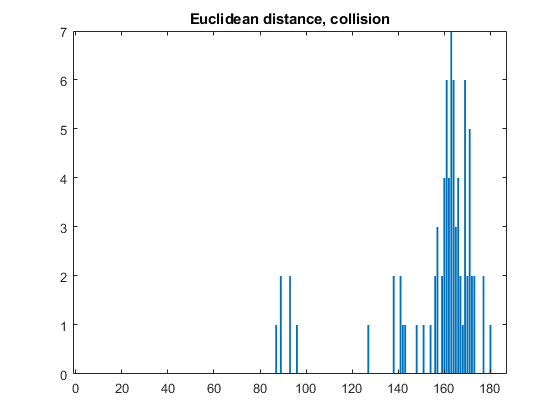

Parameters:


Mean= 156.8


Variance = 440.9722


estP = 0.8430

Compared to characterization: 


Mean= 80.5112


Variance= 45.6614


P= 0.43286


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 4.6218e-17

st = struct with fields:
    chi2stat: 89.1170
          df: 6
       edges: [-0.5000 153.5000 154.5000 155.5000 156.5000 157.5000 158.5000 159.5000 160.5000 186.5000]
           O: [15 1 0 2 3 0 2 4 53]
           E: [19.9124 5.2942 5.8693 6.2630 6.4264 6.3339 5.9896 5.4276 18.4835]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 80.2134
          df: 0
       edges: [-0.5000 80.5000 186.5000]
           O: [0 80]
           E: [40.0533 39.9467]


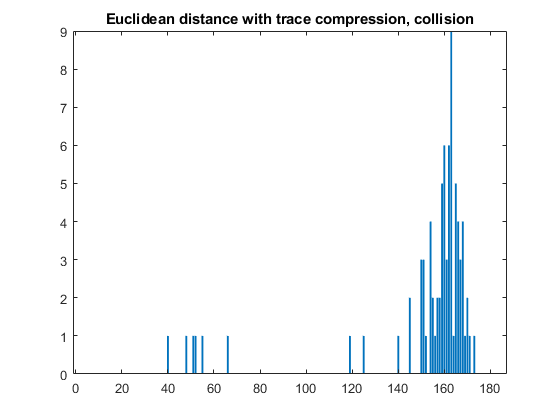

Parameters:


Mean= 151.3625


Variance = 890.5378


estP = 0.8138

Compared to characterization: 


Mean= 107.5903


Variance= 45.3555


P= 0.57844


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 6.0509e-16

st = struct with fields:
    chi2stat: 80.6788
          df: 5
       edges: [-0.5000 148.5000 149.5000 150.5000 151.5000 152.5000 153.5000 154.5000 186.5000]
           O: [11 0 3 3 1 0 4 58]
           E: [23.2110 5.3060 5.7194 5.9586 5.9957 5.8224 5.4521 22.5348]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 55.9499
          df: 0
       edges: [-0.5000 107.5000 186.5000]
           O: [6 74]
           E: [39.4482 40.5518]


%Collision distributions
for i = 1 : 4
    figure;
    counts = hist(collisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", collision"));
    %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(collisionResults(1,:,i)));
    disp("Variance = " + var(collisionResults(1,:,i)));
    estP = sum(collisionResults(1,:,i))/(length(collisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(collisionResults(1,:,i)),length(collisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(collisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end

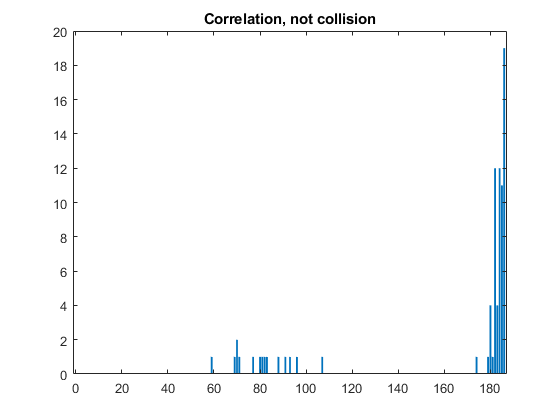

Parameters:


Mean= 164.55


Variance = 1657.9975


estP = 0.8847

Compared to characterization: 


Mean= 159.6261


Variance= 22.6342


P= 0.8582


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.2119e-44

st = struct with fields:
    chi2stat: 219.6894
          df: 6
       edges: [-0.5000 161.5000 162.5000 163.5000 164.5000 165.5000 166.5000 167.5000 168.5000 186.5000]
           O: [15 0 0 0 0 0 0 0 65]
           E: [18.9777 5.8934 6.6567 7.1617 7.3253 7.1090 6.5312 5.6664 14.6786]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 8.5624e-20

Chi-squared test:


h = 1

p = 9.9266e-37

st = struct with fields:
    chi2stat: 182.5131
          df: 6
       edges: [-0.5000 156.5000 157.5000 158.5000 159.5000 160.5000 161.5000 162.5000 163.5000 186.5000]
           O: [15 0 0 0 0 0 0 0 65]
           E: [20.0806 5.5450 6.1599 6.5655 6.7056 6.5542 6.1217 5.4554 16.8120]


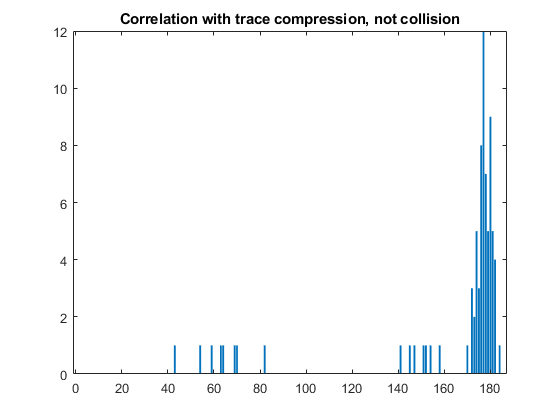

Parameters:


Mean= 163.6125


Variance = 1222.0631


estP = 0.8796

Compared to characterization: 


Mean= 122.3458


Variance= 41.87


P= 0.65777


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 7.2774e-42

st = struct with fields:
    chi2stat: 206.6516
          df: 6
       edges: [-0.5000 160.5000 161.5000 162.5000 163.5000 164.5000 165.5000 166.5000 167.5000 186.5000]
           O: [15 0 0 0 0 0 0 0 65]
           E: [18.9605 5.7813 6.5202 7.0161 7.1910 7.0071 6.4783 5.6700 15.3757]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 52.8206
          df: 0
       edges: [-0.5000 122.5000 186.5000]
           O: [8 72]
           E: [40.5000 39.5000]


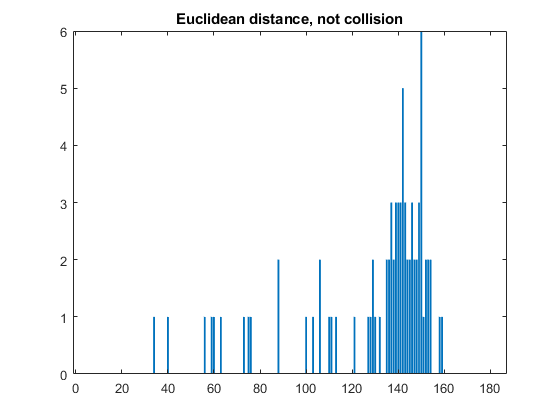

Parameters:


Mean= 129.05


Variance = 859.3899


estP = 0.6938

Compared to characterization: 


Mean= 80.5112


Variance= 45.6614


P= 0.43286


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 1

p = 1.2486e-07

st = struct with fields:
    chi2stat: 27.9443
          df: 1
       edges: [-0.5000 128.5000 129.5000 130.5000 186.5000]
           O: [21 2 1 56]
           E: [36.8875 5.0675 5.0348 33.0102]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 0

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 48.2154
          df: 0
       edges: [-0.5000 80.5000 186.5000]
           O: [9 71]
           E: [40.0533 39.9467]


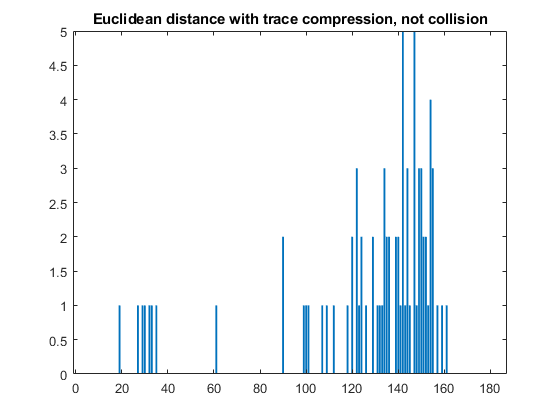

Parameters:


Mean= 126.4875


Variance = 1244.6074


estP = 0.6800

Compared to characterization: 


Mean= 107.5903


Variance= 45.3555


P= 0.57844


Execute binomial test with significance of 0.05 for estimated P:


pValue = 1

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 19.7596
          df: 0
       edges: [-0.5000 126.5000 127.5000 186.5000]
           O: [26 0 54]
           E: [39.7608 5.0040 35.2353]


Execute binomial test with significance of 0.05 for P from char:


pValueChar = 2.5844e-137

Chi-squared test:


h = 0

p = NaN

st = struct with fields:
    chi2stat: 32.3868
          df: 0
       edges: [-0.5000 107.5000 186.5000]
           O: [14 66]
           E: [39.4482 40.5518]


%Not collision distributions
for i = 1 : 4
    figure;
    counts = hist(notCollisionResults(1,:,i),bins);
    bar(bins,counts);
    title(strcat(titles(i),", not collision"));
     %Get the parameters
    disp("Parameters:");
    disp("Mean= " +  mean(notCollisionResults(1,:,i)));
    disp("Variance = " + var(notCollisionResults(1,:,i)));
    estP = sum(notCollisionResults(1,:,i))/(length(notCollisionResults)*186)
    disp("Compared to characterization: ");
    charP = selectedPoints(indexesCharacterization(i),7);
    disp("Mean= " +  186*charP);
    disp("Variance= " + 186*charP*(1-charP));
    disp("P= " + charP);
    disp("Execute binomial test with significance of 0.05 for estimated P:");
    pValue = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,estP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",estP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
    disp("Execute binomial test with significance of 0.05 for P from char:");
    pValueChar = myBinomTest(sum(notCollisionResults(1,:,i)),length(notCollisionResults)*186,charP,'Two')
    disp("Chi-squared test:");
    pd = makedist("Binomial","N",186,"p",charP);
    expectedCounts = length(notCollisionResults) * pdf(pd,bins);
    [h,p,st] = chi2gof(bins,'Ctrs',bins,'Frequency',counts,'Expected',expectedCounts,'NParams',2)
end